# Computer Vision Lab 1

# Image smoothing and simple geometric operations in Matlab

**Authors**: Emer Rodriguez Formisano and Jorge Alexander 

**Date**: 23th October 2017

## 1. Creating images of 3 channels (color images)

The RGB images are formed by 3 matrices, commonly called channels. Complete the script "exercise1.m" to implement the following steps:

1.1. Create 3 images in gray scale of size 200x200 as shown in Figure 1.

img1 = zeros([200, 200]); img1(1:200,100:200) = 1;
img2 = zeros([200, 200]); img2(100:200,1:200) = 1;
img3 = zeros([200, 200]); img3(1:100,1:100) = 1;

1.2. Combine the 3 obtained images to construct the color image shown in Figure 1(right).

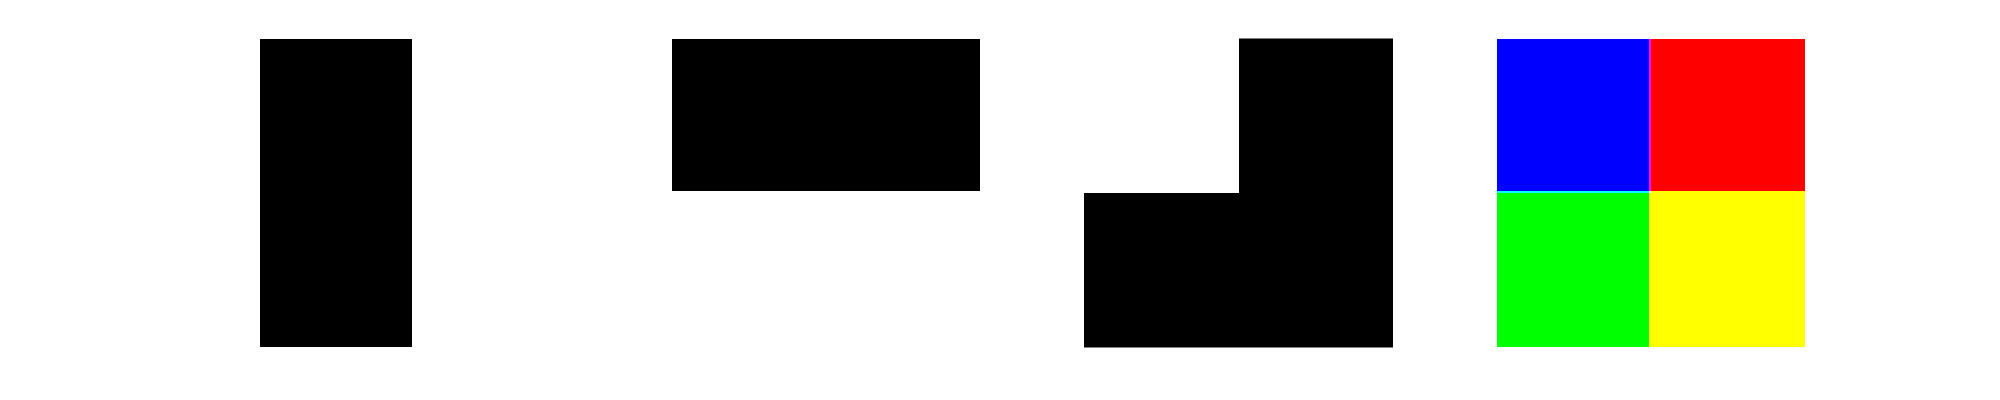

img4 = cat(3, img1, img2, img3);

set(gcf,'Position',[0 0 1000 200])
subplot(1,4,1), imshow(img1);
subplot(1,4,2), imshow(img2);
subplot(1,4,3), imshow(img3);
subplot(1,4,4), imshow(img4);

1.3. Save the color image as 3channels.jpg.

imwrite(img4, '3channels.jpg');

## 2. Displaying color images

Complete the script "exercise2.m" to implement the following steps:

2.1. Read the image buffet.jpg

buffetRGB = imread('images\buffet.jpg');

2. Display the 3 different channels RGB of the image and explain the differences and similarities in pixel values.

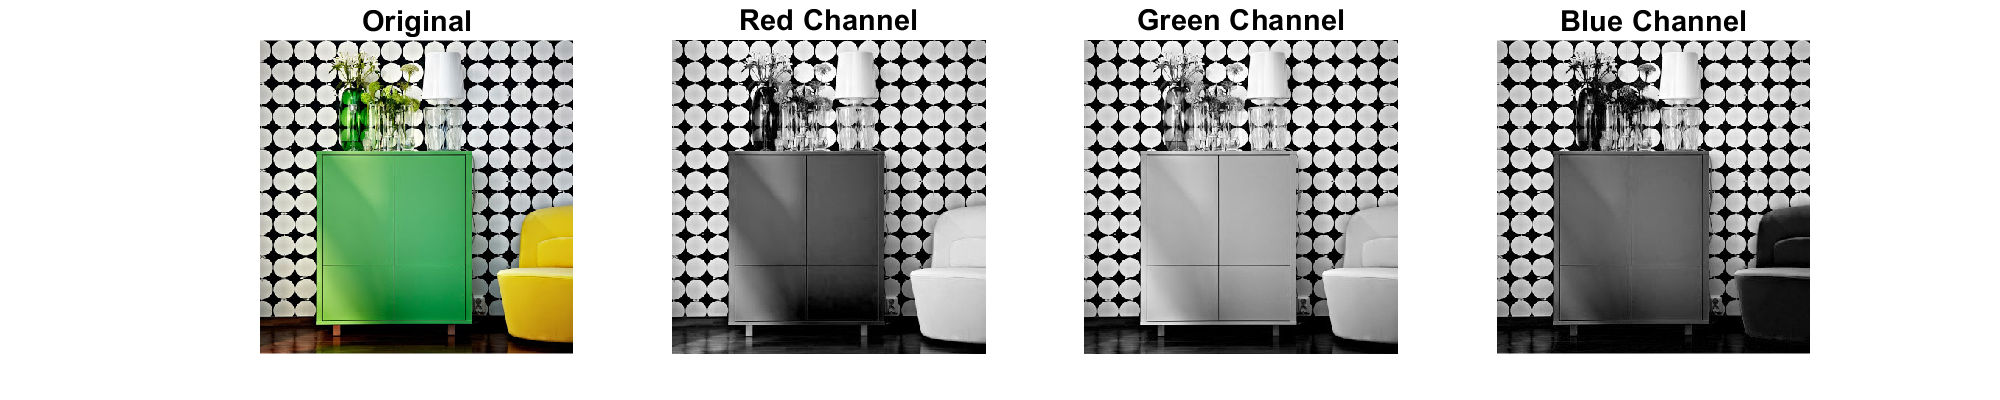

set(gcf,'Position',[0 0 1000 200])
subplot(1,4,1), imshow(buffetRGB), title('Original');
subplot(1,4,2), imshow(buffetRGB(:,:,1)), title('Red Channel');
subplot(1,4,3), imshow(buffetRGB(:,:,2)), title('Green Channel');
subplot(1,4,4), imshow(buffetRGB(:,:,3)), title('Blue Channel');

3. What would happen if we interchange the channels 1 and 2? Make the test, save the result as channel_interchange.jpg and explain what you see.

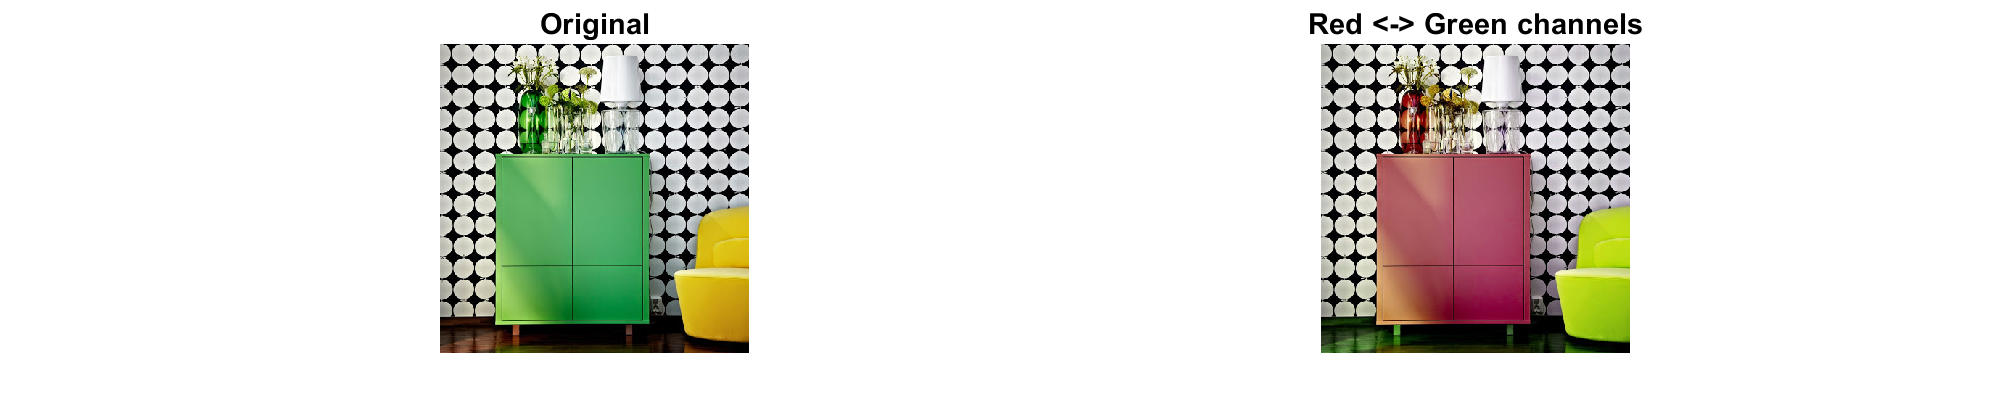

set(gcf,'Position',[0 0 1000 200])
buffet_interchannel = buffetRGB;
buffet_interchannel(:,:,1) = buffetRGB(:,:,2);
buffet_interchannel(:,:,2) = buffetRGB(:,:,1);
subplot(1,2,1), imshow(buffetRGB), title('Original');
subplot(1,2,2), imshow(buffet_interchannel), title('Red <-> Green channels');

We observed that the green cabinet becomes red as well as the green vase. The green information has been swaped with the green information. We also observed that the yellow sofa has changed colour slightly as the image has not a perfect balance of red and green channels. The blackground has not changed at all. 

imwrite(buffet_interchannel, 'channel_interchange.jpg')

4. What would happen if we multiply one of the channels by 0? Make the test, save the result as channelx0.jpg and explain what you see.

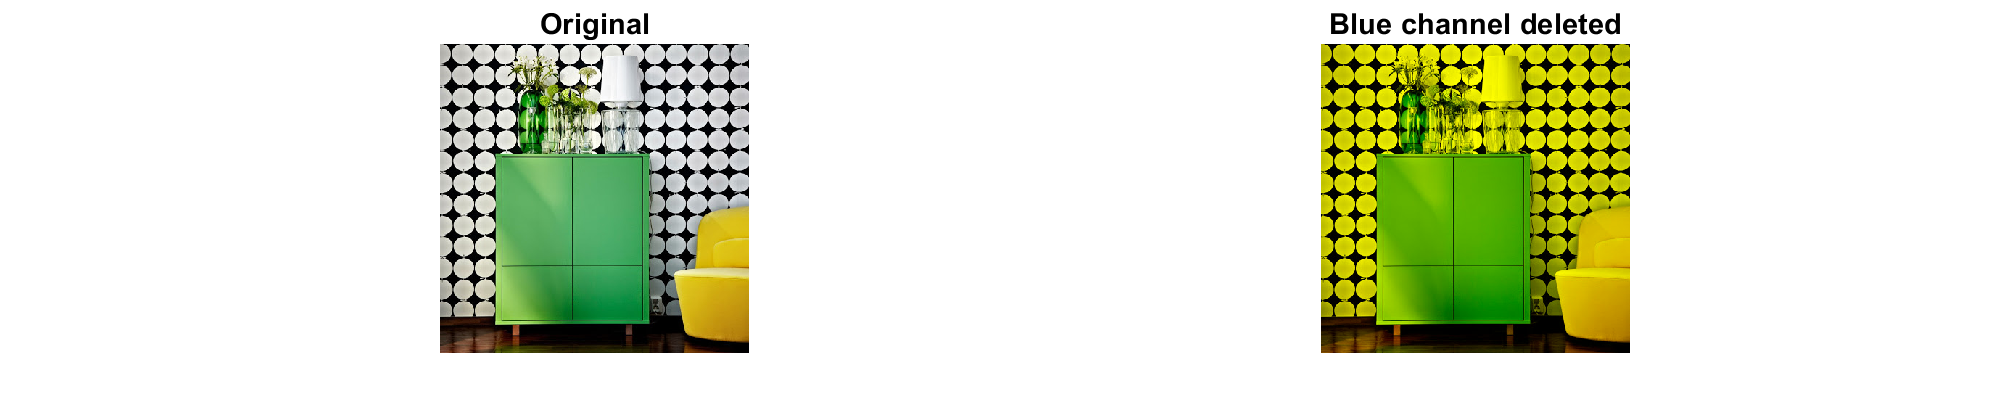

buffet_bluex0 = buffetRGB;
buffet_bluex0(:,:,3) = buffet_bluex0(:,:,3) * 0;

subplot(1,2,1), imshow(buffetRGB), title('Original');
subplot(1,2,2), imshow(buffet_bluex0), title('Blue channel deleted');

Most of the blue information in the picture is contained in the white colour. Thus, when the blue channel is deleted, the white colour changes to yellow.

imwrite(buffet_bluex0, 'channelx0.jpg')